#  Antiderivadas 

[⇦ Menú principal](matlab:open('MainMenu.mlx'))

Las tasas de cambio de las variables aparecen con frecuencia cuando se estudian interacciones de la vida real, incluidas la velocidad, la aceleración y la corriente. En los casos en los que conocemos la derivada y queremos determinar la función original, queremos encontrar la *antiderivada. *

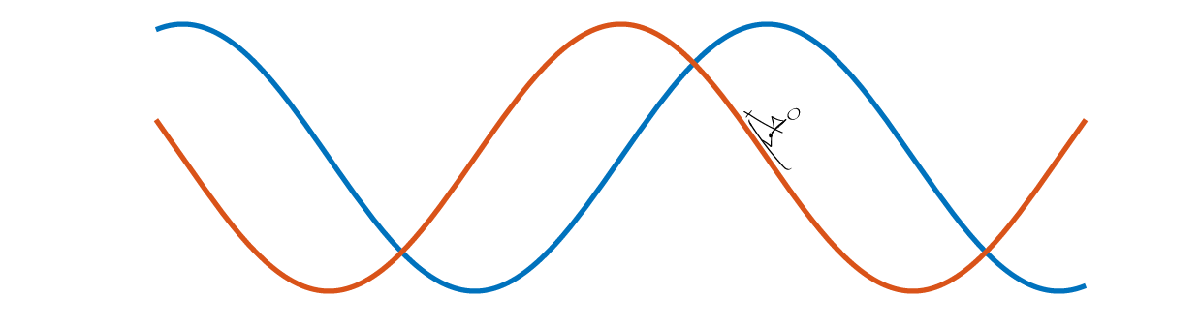

Utilizando el conocimiento de las derivadas, es posible definir una operación que deshará una derivada. 

** Antes de comenzar: **

Este live script está diseñado para usarse con el código oculto. En la pestaña **View** de la barra de herramientas de MATLAB, en la sección** View**, selecciona** Hide Code**. Alternativamente, selecciona** Hide Code** usando el ícono   en la parte superior derecha del panel Live Editor. 

 Aunque el código está oculto, cierta interactividad requiere familiaridad con MATLAB. Si necesitas más instrucción, considera realizar el [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), un tutorial en línea gratuito de 2 horas que enseña los conceptos básicos de MATLAB. 

 Para una experiencia óptima, siga las instrucciones y pasos en la secuencia indicada. Pase a una nueva sección sólo después de completar la anterior. Algunas secciones dependen de variables creadas en secciones anteriores y generarán errores si se agotan. 

## Práctica de la regla de la potencia

$\displaystyle \int x^n\; dx = \frac{x^{n+1}}{n+1}+C$ para $n \neq -1$. $(\star)$

### ** Ejercicio 1 **

Resuelve las siguientes integrales en las variables dadas. En cada caso, debes identificar el valor de $n$ y $n+1$ tal como se usa en la ecuación $(\star)$. Utiliza `C` para una constante arbitraria, según sea necesario. 

a. $\displaystyle F(x) = \int x^4\; dx$                         

an = 0;         anp1 = 0;             asoln = @(x,C) x;
CheckExercise1(an,anp1,asoln,4) 

b. $G(t) = \displaystyle \int t^{-7.3}\; dt$

bn = 0;         bnp1 = 0;             bsoln = @(t,C) t;
CheckExercise1(bn,bnp1,bsoln,-7.3) 

y c. $H(q) = \displaystyle \int q^{-1/7}\; dq$

cn = sym(0);      cnp1 = sym(0);      csoln = @(q,C) q;
CheckExercise1(cn,cnp1,csoln,-1/7) 

## ** Regla exponencial **


$$\int e^{ax}\; dx = \frac{e^{ax}}{a} + C.$$
           
$$(\diamond)$$


### ** Ejercicio 2 **

Resuelve las siguientes integrales en las variables dadas. Utiliza `C` para una constante arbitraria, según sea necesario e identifica $a$ tal como está en la ecuación $(\diamond)$. Recuerda que la notación de MATLAB para $e^x$ es `exp(x)`.

a. $\displaystyle F(x) = \int e^{6x}\; dx$

an = 0;        asoln = @(x,C) x;
CheckExercise2(an,asoln,6) 

b. $\displaystyle G(t) = \int e^{-3t}\; dt$

bn = 0;        bsoln = @(t,C) t;
CheckExercise2(bn,bsoln,-3)

##  Práctica de la regla del logaritmo 

$\displaystyle \int \frac{1}{x}\;dx = \ln(|x|)+C$ para $x <0$ o $x>0$. 

### ** Ejercicio 3 **

Resuelve las siguientes integrales en las variables dadas. Utiliza `C` para una constante arbitraria, según sea necesario. Recuerda que la notación de MATLAB para $\ln(x)$ es `log(x)` y para $|x|$ es `abs(x)`. 

a. $\displaystyle F(r) = \int \frac{1}{r}\; dr$

asoln = @(r,C) r;
CheckExercise3(asoln,1,"ln") 

b. $\displaystyle H(w) = \int \frac{1}{8w}\; dw$

csoln = @(w,C) w;
CheckExercise3(csoln,1/8,"ln")

##  Práctica de la regla del coseno 


$$\int \cos(ax)\; dx = \frac{1}{a}\sin(ax) + C$$


### ** Ejercicio 4 **

Resuelve las siguientes integrales en las variables dadas. Utiliza `C` para una constante arbitraria, según sea necesario. 

a. $\displaystyle F(r) = \int \cos(4r)\; dr$

asoln = @(r,C) r;
CheckExercise3(asoln,4,"cos") 

b. $\displaystyle G(t) = \int \cos(-9t)\; dt$ 

bsoln = @(t,C) t;
CheckExercise3(bsoln,-9,"cos")

c.$\displaystyle H(\theta) = \int \cos\left(\frac{2\theta}{3}\right)\; d\theta$             Nota: $\theta$ debe ser `theta` en la solución escrita

csoln = @(theta,C) theta;
CheckExercise3(csoln,2/3,"cos")

##  Práctica de la regla del seno 


$$\int \sin(ax)\; dx = -\frac{1}{a}\cos(ax)+C.$$


### ** Ejercicio 5 **

Resuelve las siguientes integrales en las variables dadas. Utiliza `C` para una constante arbitraria, según sea necesario. 

a. $\displaystyle F(r) = \int \sin(9r)\; dr$

asoln = @(r,C) r;
CheckExercise3(asoln,9,"sin") 

b. $\displaystyle G(t) = \int \sin(-2t)\; dt$ 

bsoln = @(t,C) t;
CheckExercise3(bsoln,-2,"sin")

     c. $\displaystyle H(\theta) = \int \sin\left(-\frac{\pi \theta}{2}\right)\; d\theta$ Nota: La variable $\theta$ debe ser `theta` en la solución escrita y la constante $\pi$ debe ser `pi`. 

cinput = str2sym(" theta");
csoln = matlabFunction(cinput,Vars=[sym("theta"),sym("C")]);
CheckExercise3(csoln,-pi/2,"sin")

##  Practica antiderivadas aleatorias 

  **Consejo**. La sintaxis de MATLAB para $7t^{2/3}$ es 7 `*t^(2/3)`. La variable que uses en la solución es importante, al igual que el uso apropiado de paréntesis y operadores de multiplicación. 

% Borrar variables que pueden reutilizarse en otras partes de este módulo.
clear errorCount totAntiProbs totAttempts adjustcount lastFive myFun varChoice
syms t r x z C                       % Declarar variables simbólicas
varOpts = [t r x z];                 % Definir la lista de variables a utilizar en los problemas.
errorCount = 0;                      % Inicializar un recuento de errores
totAntiProbs = 0;                    % Inicializar un recuento del total de problemas intentados
totAttempts = 0;                     % Inicializar un recuento del total de soluciones ofrecidas
adjustCount = 0;                     % Conservar los recuentos si el usuario vuelve a enviar una solución
lastFive = zeros(1,5);               % Inicializar una matriz para registrar los últimos cinco resultados de la solución
 
disp("Valores inicializados para la práctica de antiderivadas.")

% Compruebe si la sección anterior se ha ejecutado
% Si no, proporcione una advertencia. Si es así genera un problema.
if ~exist("totAntiProbs","var")
    warning("Debes inicializar los valores antes de poder generar un problema.")
else
    [myFun,varChoice] = GenProbType(varOpts,1);  % GenProbType se define en Funciones auxiliares
    % GenProbType configura una variable y genera una función aleatoria
    totAntiProbs = totAntiProbs+1;     % Aumentar el recuento total de problemas intentados.
end
                                   % Run this section 

myAnswer = r;     % Solución definida por el usuario, valor predeterminado r
totAttempts = totAttempts + 1;       % Recuento de actualizaciones del total de intentos de solución
[lastFive,errorCount,totAttempts,adjustCount] = ResubmissionCheck(totAttempts,totAntiProbs, ...
    adjustCount,myFun,varChoice,myAnswer,errorCount,lastFive);
% ResubmissionCheck is defined in Helper Functions
% ResubmissionCheck records the attempt and provides appropriate feedback
                         % Run this section 

Una vez que haya completado suficiente práctica, realice un seguimiento de los resultados generales de su práctica aquí: 

 
AnalyzeResults(totAntiProbs,errorCount,totAttempts,adjustCount,lastFive)

###  App de práctica

Puedes practicar en la app Calculus Flashcards. Puede iniciar la aplicación haciendo clic en la imagen a continuación. Debes configurar el tipo de problema como "**Integrales de funciones**" en la sección **Integrales**. La aplicación se abrirá en una nueva ventana. 

[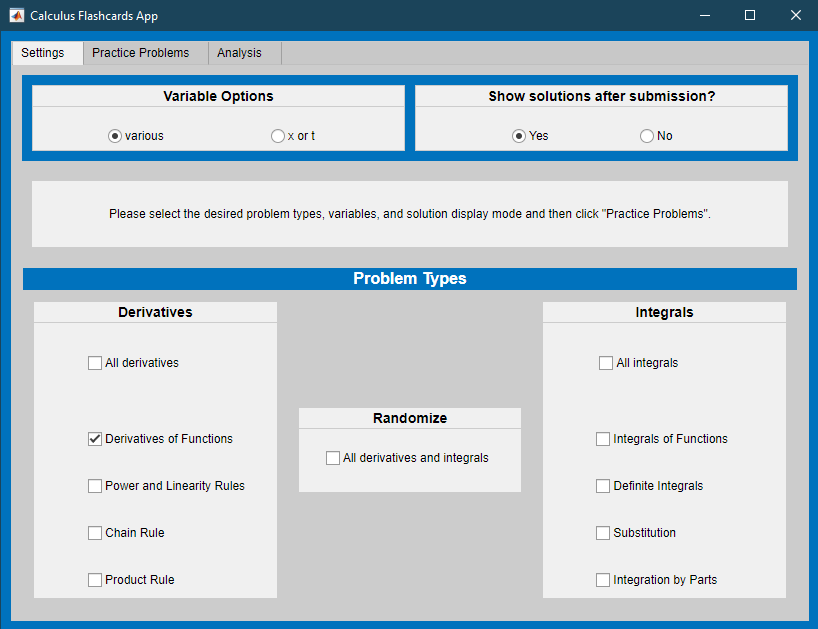](matlab: CalculusFlashcards)

 
TarjetasDeCalculo

[⇦ Menú principal](matlab:open('MainMenu.mlx'))

##  Funciones auxiliares locales 

Si deseas ver los detalles del código, selecciona la pestaña **View** y selecciona **Output inline**. Como alternativa, selecciona **Output inline** usando el ícono   en la parte superior derecha del panel Live Editor. 

** Verifique el ejercicio 1 **

Verifique que se haya realizado algún esfuerzo y brinde la retroalimentación adecuada. 

function CheckExercise1(n,np1,mysoln,nReal)
syms x C
if n == nReal
    if nReal+1 == np1
        if isAlways(diff(mysoln(x,C),x)==x^(nReal),"Unknown","false")
            if diff(mysoln(x,C),C)~=0
                disp("Esta solución es correcta.")
            else
                disp("Aunque tienes la identificación correcta de n y n+1, tu respuesta es incorrecta porque le falta +C")
            end
        else
            disp("Aunque tienes la identificación correcta de n y n+1, tu respuesta es incorrecta. Por favor, revisa la regla de potencia.")
        end
    elseif np1 == 0
        disp("Has comenzado el problema. Por favor, termínalo antes de enviarlo.")
    else
        disp("Aunque tienes la identificación correcta de n, tienes un valor incorrecto para n+1. Por favor, revisa tu aritmética.")
    end
elseif n == 0 && np1 == 0 && isequal(mysoln(x,C),x)
    disp("Por favor, intenta resolver el problema antes de enviarlo.")
else
    disp("Ese no es el valor correcto de n. Por favor, revisa tus patrones e inténtalo de nuevo.")
end
end

** Verifique el ejercicio 2 **

Verifique que se haya hecho algún esfuerzo y brinde la retroalimentación adecuada. 

function CheckExercise2(n,mysoln,nReal)
syms x C
if n == nReal
    if isAlways(diff(mysoln(x,C),x)==exp(nReal*x),"Unknown","false")
        if diff(mysoln(x,C),C)~=0
            disp("Esta solución es correcta.")
        else
            disp("Aunque tienes la identificación correcta de a, tu respuesta es incorrecta porque le falta +C")
        end
    else
        disp("Aunque tienes la identificación correcta de a, tu respuesta es incorrecta. Por favor, revisa la regla exponencial.")
    end
elseif n == 0 && isequal(mysoln(x,C),x)
    disp("Por favor, intenta resolver el problema antes de enviarlo.")
else
    disp("Ese no es el valor correcto de a. Por favor, revisa tus patrones e inténtalo de nuevo.")
end
end

** Verifique el ejercicio 3 **

Verifique que se haya hecho algún esfuerzo y brinde la retroalimentación adecuada. 

function CheckExercise3(mysoln,a,type)
syms x C
assume(x,"real")    % Agregue suposiciones sobre x para evitar derivadas complejas
switch type
    case "ln"
        integrand = @(x,par) par/x;
    case "cos"
        integrand = @(x,par) cos(par*x);
    case "sin"
        integrand = @(x,par) sin(par*x);
end
if isequal(mysoln(x,C),x)
    disp("Por favor, intenta resolver el problema antes de enviarlo.")
elseif isAlways(diff(mysoln(x,C),x)==integrand(x,a),"Unknown","false")
    if diff(mysoln(x,C),C)~=0
        disp("Esta solución es correcta.")
    else
        disp("Tu respuesta es incorrecta porque le falta +C")
    end
else
    switch type
        case "ln"
            disp("Tu respuesta es incorrecta. Por favor, revisa la regla del logaritmo.")
        case "cos"
            disp("Tu respuesta es incorrecta. Por favor, revisa la regla del coseno.")
        case "sin"
            disp("Tu respuesta es incorrecta. Por favor, revisa la regla del seno.")
    end
end
assume(x,"clear")
end

** Practicar funciones de generación de problemas **

Analizar los resultados y dar retroalimentación 

function AnalyzeResults(totProbs,errorCount,totAttempts,adjustCount,lastFive)
% analiceResults proporciona retroalimentación en el caso de un solo tipo de problema
% totProbs, errorCount, totAttempts y ajustaCount son números enteros
% lastFive es un vector
overallRight = (1 - sum(errorCount)/sum(totProbs))*100;
if sum(totAttempts) > sum(totProbs)
    % Si el usuario ha vuelto a enviar después de ver la solución, responda
    disp("¿Por qué estás reenviando después de saber la solución?")
    disp("Los reenvíos no se incluyen en tus estadísticas.")
    if sum(adjustCount) > 1
        % Si el usuario está reenviando repetidamente, anímalo a usar
        % este generador de problemas como se pretende, comenzando de nuevo
        disp("Has reenviado " + sum(adjustCount) + " veces.")
        disp("Por favor, considera reiniciar el conteo usando el botón `Inicializar Valores'.")
    end
end
if totProbs >= 5
    lastCorrect = sum(lastFive);
    % If more than 5 problems have been attempted, provide grammatically
    % appropriate feedback on success rates
    if lastCorrect > 1
str = compose("La tasa de éxito general es %.1f%% en %i problemas totales \n\n" + ...
            "De los últimos cinco, %i fueron correctos.",overallRight,totProbs,lastCorrect);
    elseif lastCorrect == 1
        str = compose("La tasa de éxito general es %.1f%% en %i problemas totales \n\n" + ...
            "De los últimos cinco, uno fue correcto.",overallRight,totProbs);
    elseif lastCorrect == 0
        str = compose("La tasa de éxito general es %.1f%% en %i problemas totales \n\n" + ...
            "De los últimos cinco, ninguno fue correcto.",overallRight,totProbs);
    end
else
    % Si se han intentado menos de 5 problemas, fomente la perseverancia.
    str = compose("La tasa de éxito general es %.1f%% en %i problemas totales \n\n" + ...
        "Por favor, haz al menos cinco problemas.",overallRight,totProbs);
end
disp(str)
end 

Verificar la corrección de la solución enviada 

function [lastFive,errorCount] = Check1(myFunc,myVar,myAnswer,errorCount,lastFive)
% check1 genera respuestas correctas integrando y actualizando
% errorCount y lastFive
%
% Entradas: myFunc es la función simbólica para diferenciar 
% o integrar myVar es la variable independiente myAnswer es 
% la función o número de prueba simbólico errorCount es un número 
% entero que rastrea el total de intentos incorrectos *-- -* 
% lastFive es un vector que rastrea los últimos cinco intentos 
% Salida: correctAnswer es una función simbólica que es la solución 
% a probType aplicada a myFunc(myVar) con bds
syms C
correctAnswer = int(myFunc,myVar)+C;
lastFive(1:4) = lastFive(2:5);
disp("Cuando se simplifica, esta función es: ")
disp(myAnswer)
if correctAnswer == myAnswer
    disp("Esa respuesta es correcta.")
    lastFive(5) = 1;
elseif isAlways(diff(myAnswer,myVar)-myFunc==0,"Unknown","false")
    if diff(myAnswer,C) == 1
        disp("Esa respuesta es correcta. Otra forma posible es:")
        disp(correctAnswer-C + "C")
        lastFive(5) = 1;
    else
        disp("Te falta un +C.")
        disp("La respuesta correcta es:")
        correctAnswer %#ok<NOPRT>
        errorCount = errorCount + 1;
        lastFive(5) = 0;
    end
else
    disp("Eso es incorrecto. La respuesta correcta es:")
    correctAnswer %#ok<NOPRT>
    errorCount = errorCount + 1;
    disp("Por favor, inténtalo de nuevo con un nuevo problema.")
    lastFive(5) = 0;
end
end 

Construir un problema para mostrar 

function [myFun,varChoice] = GenProbType(varOpts,probType)
% genProbType configura una variable y genera una función aleatoria
%
% Entradas: varOpts es una matriz de posibles variables
% probType es una cadena que identifica el tipo de función
% Salidas: myFun es una función simbólica
% varChoice es la variable independiente
% probType es un número entero que rastrea el tipo de pregunta formulada
% [a, b] son ��los límites de la integral definida, si es necesario

% Seleccione aleatoriamente una variable del conjunto varOpts
varChoice = varOpts(randi([1 length(varOpts)],1));

% Utilice genFunDiff para generar funciones simples
% genFunDiff se define en Funciones auxiliares
% Las entradas a genFunDiff son la variable varChoice, un rango de valores
% entre los cuales seleccionar coeficientes y un valor que indica cuál Las advertencias
% ya se han impreso durante la generación del problema.
switch probType
    case 1 % problema integral simple
        syms f(x) x F(x) %#ok<NASGU>
        [f(x),~] = GenFunDiff([1 10],x,[1 10],0);
        myFun = diff(f(varChoice),varChoice);
        % Mostrar el problema integral
        disp("Calcula la integral:")
        displayFormula("F(varChoice) == int(myFun,varChoice)")
end
end 

Generar funciones aleatorias apropiadas 

function [myFunc,type] = GenFunDiff(bds,var,range,prevFuncType)
syms f(t)                    % Crear una función simbólica f(t)
params = randi(bds,[1 4]);   % Elija aleatoriamente los valores de los parámetros
shift = randi([0 max(abs(bds))],1); % Elija aleatoriamente un turno que puede ser 0
sgns = randi([0 1],[1 3]);   % Elija aleatoriamente signos +/-
type = randi(range,1);


% Para facilitar la lectura, cree los parámetros a,b,c yd.
a = (-1)^sgns(1)*params(1);
b = (-1)^sgns(2)*params(2);
c = max(params(3),params(4));  % c > 0, solo se usa como denominador
d = (-1)^sgns(3)*shift;

switch type
    case 1
        f(t) = a*t^b+c*t^d;
    case 2
        f(t) = a*t^b+t^(d/c);
    case 3
        f(t) = t^a+c*t^b+t^d;
    case 4
        f(t) = t^a+c*t^b+d;
    case 5
        f(t) = a*t^(b);
    case 6
        f(t) = a*t^(b/c);
    case 7
        f(t) = a*log(abs(b)*t);
        if (prevFuncType ~= 7)&&(prevFuncType ~= 11)
            disp("Recuerda que log(x) es la notación " + ...
                "para un logaritmo natural en MATLAB.")
        end
    case 8
        f(t) = a*exp(b*t);
        if prevFuncType ~= 8
        disp("Recuerda que exp(x) es la notación para e^x en MATLAB.")
        end
    case 9
        f(t) = a*sin(b*t);
    case 10
        f(t) = a*cos(b*t);
    case 11
        f(t) = a*log(ceil(c/4)*t);
        if (prevFuncType ~= 7)&&(prevFuncType ~= 11)
            disp("Recuerda que log(x) es la notación " + ...
                "para un logaritmo natural en MATLAB.")


        end
    case 12
        f(t) = a*t^c;
    case 13
        f(t) = a*sin(b*t+d)*exp(b*t);
    case 14
        f(t) = a*cos(b*t+d)*exp(b*t);
end
myFunc = f(var);
end 

Manejar envíos 

function [lastFive,errorCount,totAttempts,adjustCount] = ResubmissionCheck(totAttempts,totProbs, ...
    adjustCount,myFun,varChoice,myAnswer,errorCount,lastFive)
if sum(totAttempts > (totProbs + adjustCount))
    % Check if this is a resubmission after the solution has been provided
    % If so, provide feedback but do not record in errorCount or lastFive
    % If not, update the values of lastFive and errorCount using check1
    adjustCount = totAttempts-totProbs;
    [lastFive,errorCount] = Check1(myFun,varChoice,myAnswer,errorCount,lastFive);

elseif sum(totAttempts < (totProbs + adjustCount))
    % Check if this is a submission after the generation of multiple problems that were skipped
    % If so, add the skipped problems to errorCount and adjust the totAttempts
    % to compensate. Explain to the user that skipped problems count as incorrect.
    numSkipped = totProbs + adjustCount - totAttempts;
    errorCount = errorCount + numSkipped;
    totAttempts = totProbs + adjustCount;
    for k = 1:length(totProbs)
        if numSkipped(k) < 5
            lastFive(k,:) = [lastFive(k,1+numSkipped:5),zeros(1,numSkipped)];
        else
            lastFive(k,:) = zeros(1,5);
        end
        if sum(numSkipped) > 1
        disp("Los "+sum(numSkipped)+" problemas generados sin intentos de solución " + ...
            "han sido incluidos en el conteo de errores.")
        disp(" ")
    elseif sum(numSkipped) == 1
        disp("El problema generado sin un intento de solución ha sido " + ...
            "incluido en el conteo de errores.")
        end
        [lastFive,errorCount] = Check1(myFun,varChoice,myAnswer,errorCount,lastFive);
    end
else
    [lastFive,errorCount] = Check1(myFun,varChoice,myAnswer,errorCount,lastFive);
end
end